clear ;


filename1='/Users/samridhisingh/Desktop/final_paper_new_vital/Participant 1/0Deg/D1/Phase_save.xlsx';
filename2='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case3\Set3\D2\Phase_save.xlsx';
filename3='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case4\D1\Phase_save.xlsx';
filename4='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case4\D2\Phase_save.xlsx';
filename5='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case3\Set1\D1\Phase_save.xlsx';
filename6='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case3\Set1\D2\Phase_save.xlsx';
filename7='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case3\Set2\D1\Phase_save.xlsx';
filename8='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\Case3\Set2\D2\Phase_save.xlsx';
% filename_hex1='C:\Users\Manvendra Singh\Downloads\Two Participants\Two Participants\HexFile_RR.xlsx';
% x_RR_all1=readmatrix(filename_hex1);
% use for clutter files
% filename_hex2='C:\Users\Manvendra Singh\Downloads\Participant 6\Participant 6\HexFile_RR.xlsx';
% x_RR_all2=readmatrix(filename_hex2);

%Process all files for a participant in one go
for k=1:1
    if k==1                                                                      
        filename=filename1;
    elseif k==2
        filename=filename2;
    elseif k==3
        filename=filename3;
    elseif k==4
        filename=filename4;
    elseif k==5
        filename=filename5;
    elseif k==6
        filename=filename6;
    elseif k==7
        filename=filename7;
    elseif k==8
        filename=filename8;
    end
        
    
    [filepath,~,~] = fileparts(filename);
    x_phase=readmatrix(filename);
    if k<9 %use k<5 for clutter files
%         x_RR=x_RR_all1(:,k+8); %k+48 for clutter files
%     elseif k>4     %use for clutter files
%         x_RR=x_RR_all2(:,k+44);
    end
    

      %process complete signal to check for sustained oscillation dominated
     %frequency for complete test duration
     % 1024 samples best suited for our case where 1512 samples taken for 152 seconds test duration
                r1=3;
                J1=27;
                x_sig=x_phase(257:1280,1); 
                [y1,y2,w1,Q1] = myemd_rr(x_sig);
                e=PlotEnergy(w1)

e = 1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    1.4467


                fs=10;
                fc=tqwt_fc(Q1,r1,J1,fs)

fc =     5.0000    3.5076    3.0535    2.6582    2.3141    2.0146    1.7538    1.5267    1.3291    1.1571    1.0073    0.8769    0.7634    0.6646    0.5785    0.5036    0.4384    0.3817    0.3323    0.2893    0.2518    0.2192    0.1908    0.1661    0.1446    0.1259    0.1096


                rr_test=zeros(2,J1);
                rr_test(1,:)=fc;
                rr_test(2,:)=e(1,1:J1);
                %find out the HR indices 
                rr_test_1=rr_test(:,(rr_test(1,:)>0.1));
                rr_test_1=rr_test_1(:,(rr_test_1(1,:)<0.6));
                [~,esort]=sort(rr_test_1(2,:),'descend');
                fc_rr_1=rr_test_1(1,esort);
                
                if length(fc_rr_1)==2
                    fc_rr_1(3)=fc_rr_1(1);
                elseif length(fc_rr_1)==1
                    fc_rr_1(2)=fc_rr_1(1);
                    fc_rr_1(3)=fc_rr_1(1);
                end
                              
                x_RR_radar_1=round(fc_rr_1(1:3),2);
                x_RR_radar_index1=round(x_RR_radar_1.*51.2);
                index_rr(1,1:3)=x_RR_radar_index1;
               
                %Find the best rpresentative of frequency in the basic and
                %first harmonic top three enrgy values
                h=histogram(index_rr(1,:),'BinWidth',3);
                [~,idxh]=sort(h.Values,'descend');
                test_index_check=h.BinEdges(idxh(1))+1; %mean of histogram width
                index_radar=test_index_check;
               
               

## RR harmonic values id estimation through RSSD

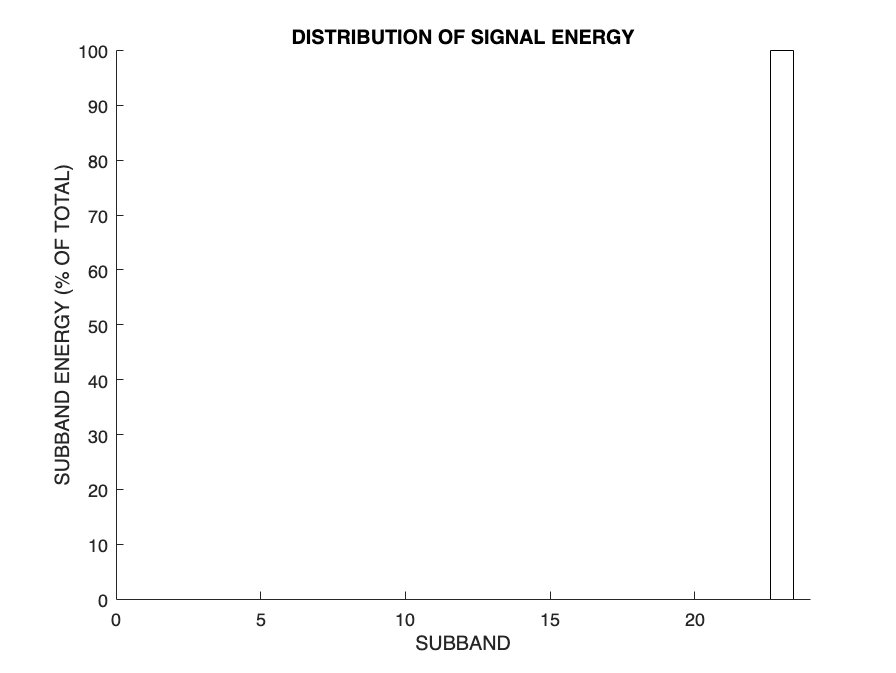


    Nr=length(x_phase); %% 
    Nchirp=512;  %% equivalent to 512*100msec = 52sec
    init_chirp = 1;
    est_window=10; %% equivalent to 10*100msec= 1sec
    noofestimates = round((Nr - Nchirp)/est_window);
    irr=zeros(noofestimates,5);
    for p = 1:noofestimates
        end_chirp = init_chirp+Nchirp-1;
        x_sig=x_phase(init_chirp:end_chirp);
        init_chirp= p*est_window +1;
        [y1,y2,w1,J1] = myemd_sec_rr(x_sig,Q1);
                e=PlotEnergy(w1);
                fc=tqwt_fc(Q1,r1,J1,fs);
                rr_test=zeros(2,J1);
                rr_test(1,:)=fc;
                rr_test(2,:)=e(1,1:J1);
                %find out the HR indices 
                rr_test_1=rr_test(:,(rr_test(1,:)>0.08));
                rr_test_1=rr_test_1(:,(rr_test_1(1,:)<0.6));
                [~,esort]=sort(rr_test_1(2,:),'descend');
                fc_rr_1=rr_test_1(1,esort);
                
                if length(fc_rr_1)==2
                    fc_rr_1(3)=fc_rr_1(1);
                elseif length(fc_rr_1)==1
                    fc_rr_1(2)=fc_rr_1(1);
                    fc_rr_1(3)=fc_rr_1(1);
                end
                                
                x_RR_radar_1=round(fc_rr_1(1:3),2);
                x_RR_radar_index1=round(x_RR_radar_1.*51.2);
                irr(p,1:3)=x_RR_radar_index1;
                
    end

    %write all hr index in a file
    noofestimates=100;
%     rr_hex=x_RR(52:51+noofestimates,1);
%     rr_hex_ind=round(rr_hex*512/600);
    rr_ind_cpm=irr;
    rr_ind_cpm(:,4)=index_radar;
%     rr_ind_cpm(:,5)=rr_hex_ind;
    f2 = fullfile(filepath,"rr_radar_index.xlsx");
%     writematrix(rr_ind_cpm,f2);
        
end